## Simulation that models how musical motor skills are retained or lost over a 30-day period based on different practice schedules

clear; clc; close all;
%forgetting curve
%stochastic element
%compare three scenarios: the "Weekend Warrior" (one long session),
% the "Consistent Student" (daily short sessions), and the % "Erratic Learner" (random intervals)

%proficiency percentage over 30days for each schedule. multiline plot
%sensetivity analysis. to show comparision of decay changes for simple and
%complex task

%parameters
P(1) = 50; % e.g p(1) skill for day 1, p(2)= p(1); copy
R= 10; %reinforcement(boost)
lambda = 0.05;
days = 30;
fatigue = 0.01; % reduces efficiency, if duration > 45



p = zeros(1, days);
rand = 0.9;
for d=2:days
    p(d) = p(d-1) * exp(-lambda); % forgeting
    if duration > 0
        p(d) = p(d-1) + R; %practice
    end
    %Fatigue
    if duration > 45
        efficiency = max(0, 1- fatigue(duration - 45)); %efficiency can not be zero
    else
        efficiency = 1;
    end
       
    
    % Make stochastic, not always perfect some days great practice, some
    % other days distracted
     %randomness, rand(0,1)
   efficiency = efficiency * (0.8 + 0.4*rand);
    

end

%%weekend warrior
p_weekend = zeros(1, days);
p_consistent = zeros(1, days);
p_erratic = zeros(1, days);
% % initialize
p_weekend(1) = 50;
p_consistent(1) = 50;
p_erratic(1) = 50;

%% weekend warrior
for d = 2:days
    p_weekend(d) = p_weekend(d-1) *exp(-lambda);
   % %{if mod(d,7) == 6 % e.g saturday
   %     duration = 170;
   % else
   %     duration =0; % no practice
   % end
   % %}
   %both weekend days
   if mod(d,7) == 6  || mod(d,7) == 0 % e.g saturday
       duration = 100;
   else
       duration =0; % no practice
   end

     if duration > 45
        efficiency = max(0, 1- fatigue*(duration - 45));%efficiency can not be zero
     else
         efficiency = 1;
      end
    
        efficiency = efficiency * (0.8 + 0.4*rand);
    
    if duration > 0
        p_weekend(d) = p_weekend(d-1) +R *efficiency;
    end
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                           
end


## Consistent Student


for d=2:days
     p_consistent(d) = p_consistent(d-1)*exp(-lambda);
     duration = 30;

    if duration > 45
        efficiency = max(0, 1- fatigue*(duration - 45));%efficiency can not be zero
     else
         efficiency = 1;
    end

    efficiency = efficiency * (0.8 + 0.4*rand);

    if duration > 0
        p_consistent(d) = p_consistent(d-1) +R *efficiency;
    end
end

## Erratic Learner

for d=2:days
    p_erratic(d) = p_erratic(d-1)*exp(-lambda);
    
    if rand > 0.5 % 50% true, 50% False
        duration = randi([20,90]);
    
    else
        duration =0;
    end
    
    if duration > 45
        efficiency = max(0, 1- fatigue*(duration - 45));%efficiency can not be zero
     else
         efficiency = 1;
    end
    
    efficiency = efficiency * (0.8 + 0.4*rand);
    
    if duration > 0
      p_erratic(d) = p_erratic(d-1) +R *efficiency;
    end

end

## Explaining models

Forgetting: Skill decreasing | exponential decay

Reinforcement: practice increases skill

Fatigue: Long sessions not effective

Randomness: Human inconsistency

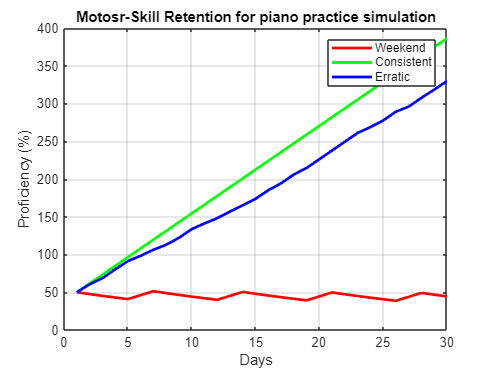

%Visualization
figure;
plot(1:days, p_weekend, 'r', 'LineWidth',2);hold on;  %plotting together
plot(1:days, p_consistent, 'g', 'LineWidth',2);
plot(1:days, p_erratic, 'b', 'LineWidth',2);
legend('Weekend','Consistent','Erratic');
xlabel('Days');
ylabel('Proficiency (%)');
title('Motosr-Skill Retention for piano practice simulation');
grid on;

%%weekend warrior graph shows spike->drop->spike->drop
any(isnan(p_consistent))

ans = logical
   0


disp(p_consistent(end-5:end))

  328.4000  340.0000  351.6000  363.2000  374.8000  386.4000



## sensetivity

lambda_simple = 0.03;
lambda_complex = 0.08;

